format longg
CP = py.importlib.import_module("CoolProp.CoolProp");

zeta_ind = 0.2;
zeta_boj_90 = 0.30;
zeta_boj_135 = zeta_boj_90 * 1.5;
zeta_boj_180 = zeta_boj_90 * 2;
zeta_buffer = 1 + 0.25;
zeta_flow = 1;
zeta_filter = 3;
zeta_skue = zeta_buffer;
% zeta_epv = 69


zeta_total = zeta_ind + 5*zeta_boj_90 + 3*zeta_boj_135 + zeta_boj_180...
    + zeta_buffer + zeta_flow + zeta_filter + zeta_skue %+ zeta_epv

zeta_total =                      10.15


# **Område 3**

**For væske**

L = 1.585 %1.95; %m

L =                      1.585


t = 0.00080; %m
d = 0.00794 - 2*t %m

d =                    0.00634


d_i = 0.008 - 2*0.0002 %m diameteren ud af kondensatoren

d_i =                     0.0076




% c_foer_kond = 5.24 % m/s
c_efter_kond = 0.1495 % m/s

c_efter_kond =                     0.1495



c_i = c_efter_kond % 0.0596112201077589; %m/s hastigheden da fluidet kommer ud af kondensatoren

c_i =                     0.1495



% c * d^2 = d_i^2 * c_i %countinuitetsligningen
c = d_i^2 * c_i / d^2

c =          0.214827493556509



rho_fluid = CP.PropsSI('D', 'T', 30 + 273.15, 'P', 886810, 'R134a') %1186.61436781861; %kg/m^3 

rho_fluid =           1188.24518242834






nu = CP.PropsSI('V', 'T', 30 + 273.15, 'P', 886810, 'R134a') % |not_imposed %m^2/s  

nu =       0.000183563655795652


Re = c * d / nu 

Re =           7.41980379092301



% Re < 2300 dermed laminart flow


% K_s = 0.003 * 10^(-3); %rukne rør af kobbe
% reltativ_rughed = K_s/ d

lambda = 64/Re  % <-----------

lambda =           8.62556501538412



Delta_p_ror = lambda * L * c^2 * rho_fluid / (d * 2)

Delta_p_ror =           59126.6605799141



Delta_p_enkelt = zeta_total * (rho_fluid * c^2)/ 2

Delta_p_enkelt =           921.287262662475


**For gas**

% c = 2.26638867101572; %m/s    
% rho_vape = 31.2106794247976; %kg/m^3 
% 
% 
% 
% L = 6.7 %1.95%1.95 %m
% t = 0.00080; %m
% d = 0.00952 - 2*t %m %0.00794 - 2*t %m % fordamper er 0.00952 - 2*t %m
% 
% nu = CP.PropsSI('V', 'T', 30 + 273.15, 'P', 886810, 'R134a') % |not_imposed %m^2/s  
% Re = c * d / nu 
% 
% % Re < 2300 dermed laminart flow
% 
% K_s = 0.003 * 10^(-3); %rukne rør af kobbe
% reltativ_rughed = K_s/ d
% 
% lambda = 64/Re  % <-----------
% 
% Delta_p_ror = lambda * L * c^2 * rho_vape / (d * 2)

% Delta_p = zeta_total * (rho * c^2)/ 2


# Fordamperen


c_for_ford = 8.41 %m/s

c_for_ford =                       8.41




d2 = 0.00952 - 2*t

d2 =                    0.00792



c2 = c_for_ford%c_uden_ford % c_for_ford %c1 * rho1 * d1^2 / (d2^2 * rho_for )

c2 =                       8.41



L = 6.7 %1.95%1.95 %m

L =                        6.7


t = 0.00080; %m
d = 0.00952 - 2*t %m %0.00794 - 2*t %m % fordamper er 0.00952 - 2*t %m

d =                    0.00792



nu = CP.PropsSI('V', 'T', 273.15 -20, 'P', 132700, 'R134a') % |not_imposed %m^2/s  

nu =       9.99947709489375e-06


rho = CP.PropsSI('D', 'T', 273.15 -20, 'P', 132700, 'R134a') % |not_imposed %m^2/s  

rho =           6.78260275854283




K_s = 0.003 * 10^(-3); %rukne rør af kobbe
reltativ_rughed = K_s/ d

reltativ_rughed =       0.000378787878787879


% Re < 2300 dermed laminart flow

K_s = 0.003 * 10^(-3); %rukne rør af kobbe
reltativ_rughed = K_s/ d

reltativ_rughed =       0.000378787878787879



% lambda = 64/Re  % <-----------
lambda = 0.035

lambda =                      0.035


Re = c2 * d2 / nu

Re =           6661.06831066327



Delta_p_ror = lambda * L * c2^2 * rho_for / (d2 * 2)

Delta_p_ror =           7101.92437790674



% Delta_p = zeta_total * (rho * c^2)/ 2'

c_uden_ford = 26.57 %m/s

c_uden_ford =                      26.57



d2 = 0.00952 - 2*t

d2 =                    0.00792



c2 = c_uden_ford%c_uden_ford % c_for_ford %c1 * rho1 * d1^2 / (d2^2 * rho_for )

c2 =                      26.57



L = 6.7 %1.95%1.95 %m

L =                        6.7


t = 0.00080; %m
d = 0.00952 - 2*t %m %0.00794 - 2*t %m % fordamper er 0.00952 - 2*t %m

d =                    0.00792



nu = CP.PropsSI('V', 'T', 273.15 -15, 'P', 132700, 'R134a') % |not_imposed %m^2/s  

nu =       1.02047877539472e-05


rho = CP.PropsSI('D', 'T', 273.15 -15, 'P', 132700, 'R134a') % |not_imposed %m^2/s  

rho =           6.62265418100098




K_s = 0.003 * 10^(-3); %rukne rør af kobbe
reltativ_rughed = K_s/ d

reltativ_rughed =       0.000378787878787879


% Re < 2300 dermed laminart flow

K_s = 0.003 * 10^(-3); %rukne rør af kobbe
reltativ_rughed = K_s/ d

reltativ_rughed =       0.000378787878787879



% lambda = 64/Re  % <-----------
lambda = 0.025

lambda =                      0.025


Re = c2 * d2 / nu

Re =           20621.1442191537



Delta_p_ror = lambda * L * c2^2 * rho_for / (d2 * 2)

Delta_p_ror =           50633.6371587257


# For Kondensatoren

**For væske**

L = 19.71 %1.95; %m

L =                      19.71


t = 0.0002; %m
d = 0.008 - 2*t %m diameteren ud af kondensatoren

d =                     0.0076



% c_fluid = 0.0596112201077589; %m/s hastigheden da fluidet kommer ud af kondensatoren


c_foer_kond = 5.24 % m/s

c_foer_kond =                       5.24


c_efter_kond = 0.1495 % m/s

c_efter_kond =                     0.1495


c = c_efter_kond

c =                     0.1495



rho_fluid = CP.PropsSI('D', 'T', 30 + 273.15, 'P', 886810, 'R134a') %1186.61436781861; %kg/m^3 

rho_fluid =           1188.24518242834




nu = CP.PropsSI('V', 'T', 30 + 273.15, 'P', 886810, 'R134a') % |not_imposed %m^2/s  

nu =       0.000183563655795652


Re = c * d / nu 

Re =           6.18967842558577



% Re < 2300 dermed laminart flow

% K_s = 0.003 * 10^(-3); %rukne rør af kobbe
% reltativ_rughed = K_s/ d

lambda = 64/Re  % <-----------

lambda =           10.3397940247507



Delta_p_ror = lambda * L * c^2 * rho_fluid / (d * 2)

Delta_p_ror =           356076.548209645


**For gas**

c_vape = c_foer_kond %2.26638867101572; %m/s    

c_vape =                       5.24


% rho_vape = 31.2106794247976; %kg/m^3 
rho_vape = CP.PropsSI('D', 'T',  82.25 + 273.15, 'P', 886810, 'R134a')

rho_vape =            34.036018249472



L = 19.71 %1.95%1.95 %m

L =                      19.71


t = 0.0002; %m
d = 0.008 - 2*t %m %0.00794 - 2*t %m % fordamper er 0.00952 - 2*t %m

d =                     0.0076



nu = CP.PropsSI('V', 'T',  82.25 + 273.15, 'P', 886810, 'R134a') % |not_imposed %m^2/s  

nu =       1.41283691185655e-05


Re = c_vape * d / nu 

Re =           2818.72590288351



% Re < 2300 dermed laminart flow

K_s = 0.003 * 10^(-3); %trukne rør af kobbe
reltativ_rughed = K_s/ d

reltativ_rughed =       0.000394736842105263



lambda = 64/Re  % <-----------

lambda =          0.022705293882789



Delta_p_ror = lambda * L * c_vape^2 * rho_vape / (d * 2)

Delta_p_ror =           27515.1247160535


enektl modstande


zeta_boj_90 = 0.30;

zeta_boj_180 = zeta_boj_90 * 2;



zeta_total = zeta_boj_180 * 56

zeta_total =                       33.6



Delta_p_fluid = zeta_total * (rho_fluid * c^2)/ 2

Delta_p_fluid =           446.167291727958


Delta_p_vape = zeta_total * (rho_vape * c_vape^2)/ 2

Delta_p_vape =           15700.3958947366


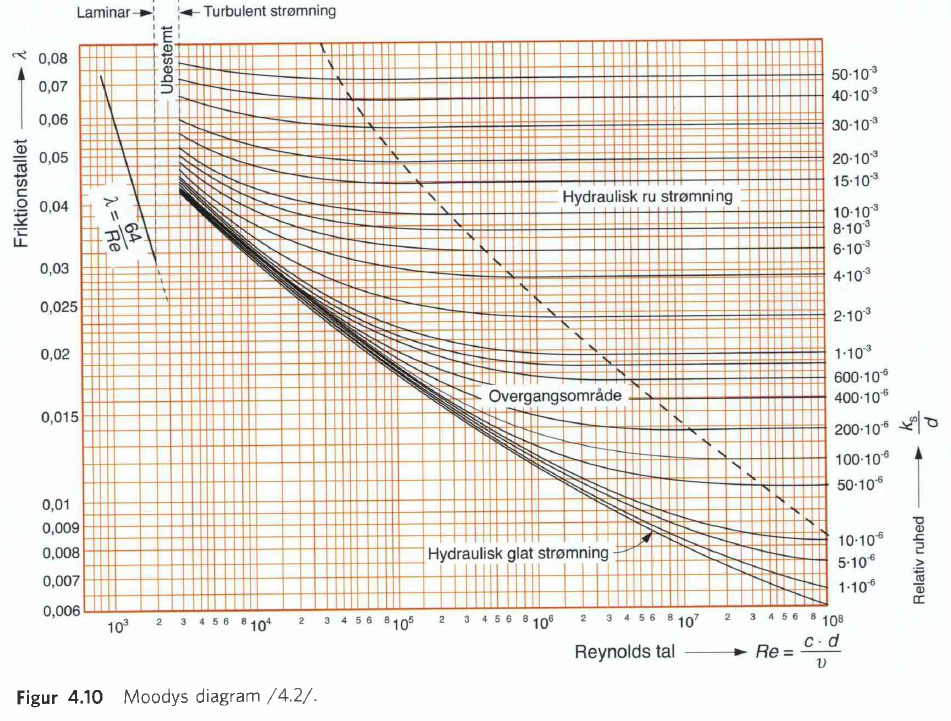

Video til coolprop

[https://www.youtube.com/watch?v=XvR10Fjph7U](https://www.youtube.com/watch?v=XvR10Fjph7U) 

For coolprop

[https://media.discordapp.net/attachments/904796150694031402/1105756331090120754/image.png](https://media.discordapp.net/attachments/904796150694031402/1105756331090120754/image.png)